Y = zeros(64,64);
Cb = zeros(64,64);
Cr = zeros(64,64);

reka = imread("lapa.jpg");

data = double(reka);
for i=1:64
    for j=1:64 %(9.1) conversion from RGB to YCbCr
         Y(i,j) = data(i,j,1)*0.299 + data(i,j,2)*0.587 + data(i,j,3)*0.114; 
         Cb(i,j) = data(i,j,1)*(-0.168736) + data(i,j,2)*(-0.331264) + data(i,j,3)*0.5 + 128;
         Cr(i,j) = data(i,j,1)*0.5 + data(i,j,2)*(-0.418688) + data(i,j,3)*(-0.081312) + 128;
    end
end



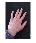


%binarization
maska = zeros(64,64);
%seems to be ok 
Ta = 100; %100
Tb = 150; %150
Tc = 100; %100
Td = 136; %136
for i=1:64
    for j=1:64
        if (Cb(i,j)<Tb) && (Cb(i,j)>Ta) && (Cr(i,j)<Td) && (Cr(i,j)>Tc)
            maska(i,j)=1;
        else
            maska(i,j)=0;
        end
        
    end
end

A = imread("lapa.jpg");
figure 
imshow(A)

imshow(maska)


%median filtering
maska_po_filtracji = medfilt2(maska);
imshow(maska_po_filtracji)

m00 = 0;
m10 = 0;
m01 = 0;
for i=1:64
    for j=1:64
        m00 = maska(i,j) + m00;
        m01 = maska(i,j)*j + m01;
        m10 = maska(i,j)*i + m10;
    end
end

%specific gravity
xciez = m10/m00;
yciez = m01/m00;
imshow(maska_po_filtracji)
hold on;
plot(0:1:64, yciez*ones(65),'r')
hold on;
plot(ones(65)*xciez, 0:1:64,'r')